clear 
clc

## Parameters Pre-setting

V0 = 0.895;                     % input swing
C1 = 38.72E-12;                 % load cap
Fs = 2E6;                       % sample rate
Fin0 = Fs * 499 / 1024;           % input frequency (Hz)
% Ron0 = 6.5*4;                  % for m*(W/L) = 16*3u/200n
% NUM_FRE = length(wt);           % number of frequency
% NUM_SAM = 1024;                 % number of sample point
alpha = -1.15;
VTH = 0.457;

## Target: THD = 90dB

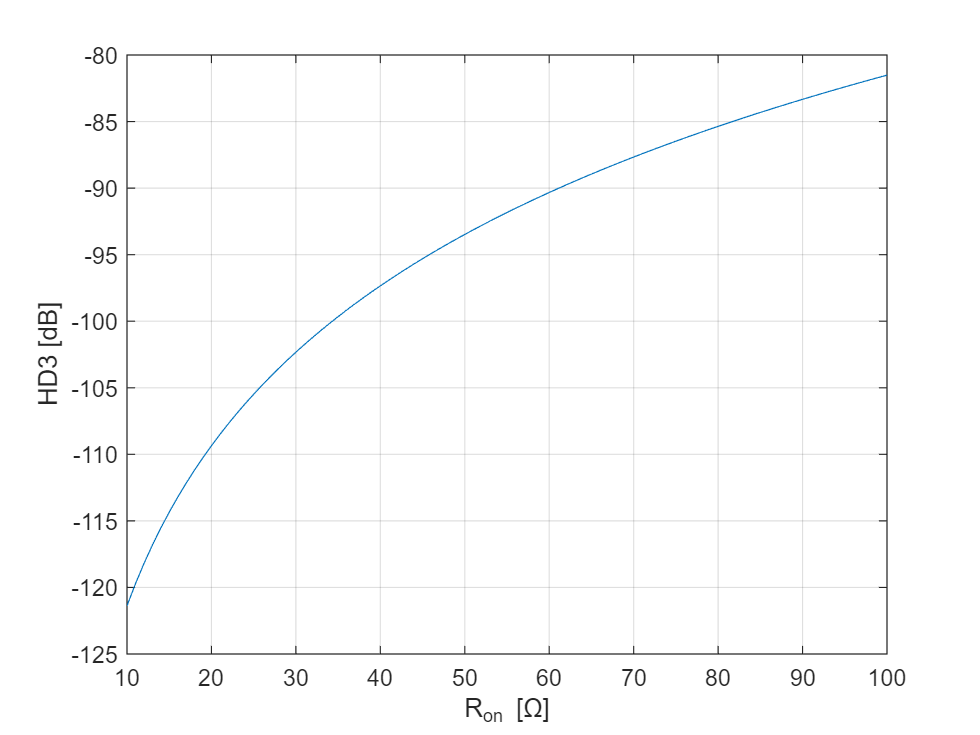

% Source-Drain Exchange
ron0 = 10:100;
HD3_1 = getHD_Calculation(ron0, V0, C1, Fin0, alpha);
figure
plot(ron0, HD3_1);
xlabel("R_{on} [\Omega]");
ylabel("HD3 [dB]");
grid on;


% Set Ron = 39 Ohms -> m*(W/L) = 8*2u/200n
getHD_Calculation(52, V0, C1, Fin0, alpha)

ans = -92.8022

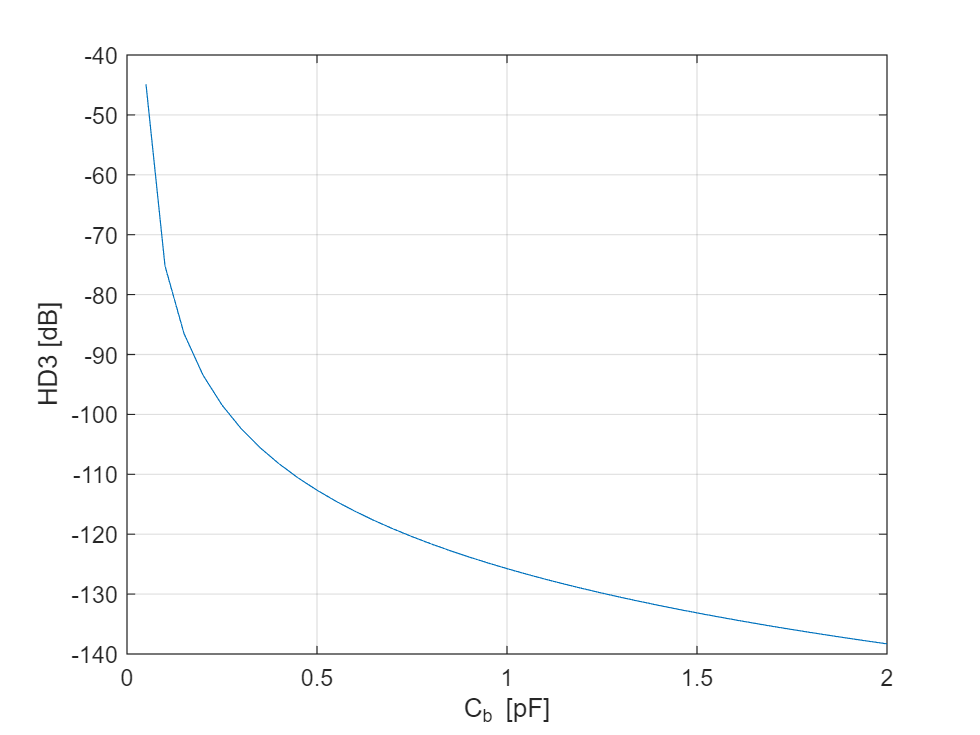


% Cap Switch-Mode
cb = 0:0.05:2;
C10 = 0;
C20 = 0;
C30 = 0;
Cp1 = 0.011;
Cp2 = 0.01;
Cp3 = 0.01;
Ctot = cb + C10 + C20 + C30 + Cp1 + Cp2 + Cp3;
KC = 0.82;
Ck1 = C10+Cp1 + C20 + KC*Cp2;
Ck2 = C30 +KC*Cp3;
Vgs0 = (cb*1.8 - (Ck1 + Ck2)*0.9) ./ Ctot;
phi = 2*pi*Fin0*(255E-9);
KFcos = cos(phi) ;
KFsin = sin(phi) ;
Csum = sqrt((Ck1+Ck2*KFcos)^2 + (Ck2*KFsin)^2);
Vgs1 =  Csum ./ Ctot * V0 ;
KV = Vgs1 ./ (Vgs0-VTH);
% Calculate Ron
Ron = 1./((Vgs0-VTH)*(280E-6 * 4 * 3 / 0.2));
% getHD_Cap_Track(V0, C1, Fin, [cb, 0, 0, 0])
R2 = (KV.^2 + KV.^4).* Ron ./ 2;
HD3 = mag2db(R2.*C1*Fin0*pi*V0);

figure
plot(cb, HD3)
xlabel("C_{b} [pF]");
ylabel("HD3 [dB]");
grid on;

% Display result
fprintf("Vgs0 = %.2f dB",mag2db(Vgs0))

Vgs0 = NaN dBVgs0 = -1.87 dBVgs0 = 1.48 dBVgs0 = 2.64 dBVgs0 = 3.24 dBVgs0 = 3.60 dBVgs0 = 3.85 dBVgs0 = 4.02 dBVgs0 = 4.15 dBVgs0 = 4.26 dBVgs0 = 4.34 dBVgs0 = 4.41 dBVgs0 = 4.47 dBVgs0 = 4.52 dBVgs0 = 4.56 dBVgs0 = 4.59 dBVgs0 = 4.63 dBVgs0 = 4.65 dBVgs0 = 4.68 dBVgs0 = 4.70 dBVgs0 = 4.72 dBVgs0 = 4.74 dBVgs0 = 4.76 dBVgs0 = 4.77 dBVgs0 = 4.78 dBVgs0 = 4.80 dBVgs0 = 4.81 dBVgs0 = 4.82 dBVgs0 = 4.83 dBVgs0 = 4.84 dBVgs0 = 4.85 dBVgs0 = 4.86 dBVgs0 = 4.86 dBVgs0 = 4.87 dBVgs0 = 4.88 dBVgs0 = 4.88 dBVgs0 = 4.89 dBVgs0 = 4.90 dBVgs0 = 4.90 dBVgs0 = 4.91 dBVgs0 = 4.91 dB

fprintf("Vgs1 = %.2f dB",mag2db(Vgs1))

Vgs1 = -4.37 dBVgs1 = -12.71 dBVgs1 = -16.89 dBVgs1 = -19.69 dBVgs1 = -21.81 dBVgs1 = -23.52 dBVgs1 = -24.94 dBVgs1 = -26.16 dBVgs1 = -27.23 dBVgs1 = -28.18 dBVgs1 = -29.04 dBVgs1 = -29.82 dBVgs1 = -30.54 dBVgs1 = -31.20 dBVgs1 = -31.82 dBVgs1 = -32.39 dBVgs1 = -32.93 dBVgs1 = -33.44 dBVgs1 = -33.92 dBVgs1 = -34.37 dBVgs1 = -34.81 dBVgs1 = -35.22 dBVgs1 = -35.61 dBVgs1 = -35.99 dBVgs1 = -36.35 dBVgs1 = -36.69 dBVgs1 = -37.02 dBVgs1 = -37.34 dBVgs1 = -37.65 dBVgs1 = -37.95 dBVgs1 = -38.24 dBVgs1 = -38.52 dBVgs1 = -38.79 dBVgs1 = -39.05 dBVgs1 = -39.31 dBVgs1 = -39.55 dBVgs1 = -39.79 dBVgs1 = -40.03 dBVgs1 = -40.26 dBVgs1 = -40.48 dBVgs1 = -40.70 dB

fprintf("Ron = %.2f dB",mag2db(Ron))

Ron = NaN dBRon = 44.62 dBRon = 38.24 dBRon = 36.42 dBRon = 35.54 dBRon = 35.02 dBRon = 34.67 dBRon = 34.42 dBRon = 34.23 dBRon = 34.09 dBRon = 33.97 dBRon = 33.88 dBRon = 33.80 dBRon = 33.73 dBRon = 33.68 dBRon = 33.63 dBRon = 33.58 dBRon = 33.54 dBRon = 33.51 dBRon = 33.48 dBRon = 33.45 dBRon = 33.43 dBRon = 33.41 dBRon = 33.38 dBRon = 33.37 dBRon = 33.35 dBRon = 33.33 dBRon = 33.32 dBRon = 33.30 dBRon = 33.29 dBRon = 33.28 dBRon = 33.27 dBRon = 33.26 dBRon = 33.25 dBRon = 33.24 dBRon = 33.23 dBRon = 33.22 dBRon = 33.21 dBRon = 33.21 dBRon = 33.20 dBRon = 33.19 dB

% fprintf("R1 = %.2f dB",mag2db(R1))
fprintf("R2 = %.2f dB",mag2db(R2))

R2 = NaN dBR2 = 34.59 dBR2 = 4.27 dBR2 = -7.01 dBR2 = -13.96 dBR2 = -18.96 dBR2 = -22.86 dBR2 = -26.06 dBR2 = -28.76 dBR2 = -31.10 dBR2 = -33.17 dBR2 = -35.02 dBR2 = -36.69 dBR2 = -38.22 dBR2 = -39.62 dBR2 = -40.92 dBR2 = -42.12 dBR2 = -43.25 dBR2 = -44.32 dBR2 = -45.32 dBR2 = -46.26 dBR2 = -47.16 dBR2 = -48.01 dBR2 = -48.83 dBR2 = -49.60 dBR2 = -50.35 dBR2 = -51.06 dBR2 = -51.74 dBR2 = -52.40 dBR2 = -53.04 dBR2 = -53.65 dBR2 = -54.24 dBR2 = -54.82 dBR2 = -55.37 dBR2 = -55.91 dBR2 = -56.43 dBR2 = -56.93 dBR2 = -57.42 dBR2 = -57.90 dBR2 = -58.37 dBR2 = -58.82 dB

% fprintf("HD3 = %.2f dB",mag2db(R2*C1*Fin*pi*V0))


## Data Process

CSVFILE = 'Vout_fd3.csv';
opts = detectImportOptions(CSVFILE);
preview(CSVFILE, opts)

ans = 8×2 table
    sample_leafValue_Vout_cap_Cboot_2e_13_600n512_6u_linear_500n_X    sample_leafValue_Vout_cap_Cboot_2e_13_600n512_6u_linear_500n_Y
    ______________________________________________________________    ______________________________________________________________

                                 6e-07                                                            0.89172                           
                               1.1e-06                                                           -0.88284                           
                               1.6e-06                                                            0.86835                           
                               2.1e-06                                                           -0.84833                           
                               2.6e-06                                                            0.82286                           
                               3.1e-06              

opts.SelectedVariableNames = 2;
MCb1 = readmatrix(CSVFILE, opts);
MCb1(1025:end) = [];


## Single end to differential

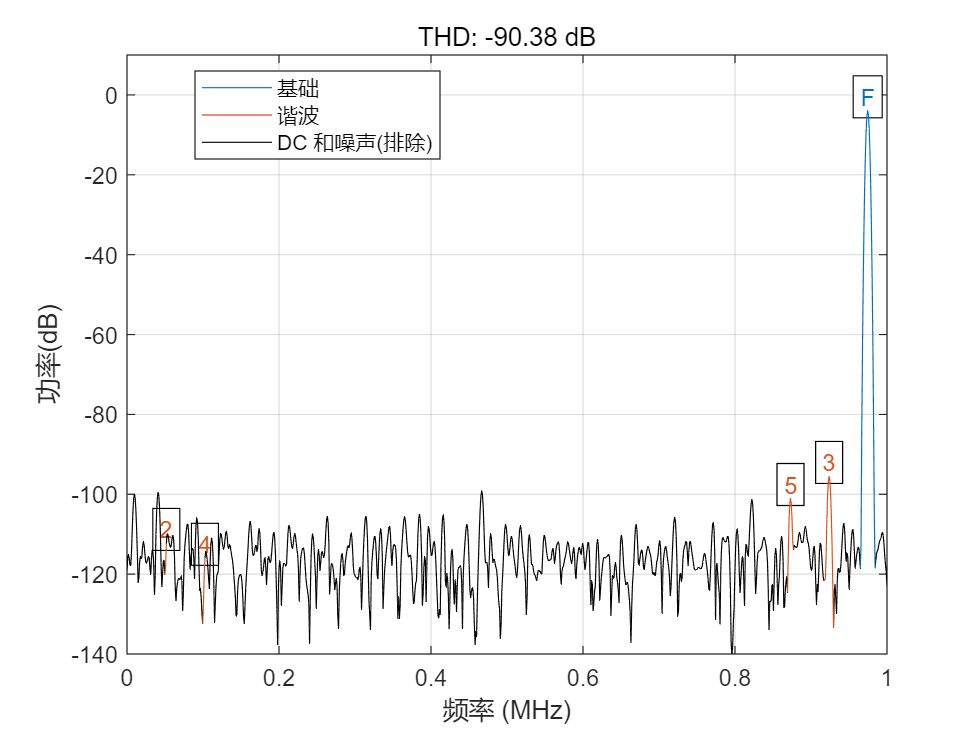

ans = -90.3810

% t= 0:(1/Fs):1023/Fs;
% M = 0.9*sin(2*pi*t*Fin) + 0.9* sin(2*pi*2*t*Fin) +0.9;
figure
thd(repmat(MCb1,2,1), Fs, 5, 'aliased')

% M_minues = 1.8 - M;
% M_differential = M - M_minues;
% figure
% plot(M);
% hold on;
% plot(M_minues)
% plot(M_differential)
% xlim([0,20])
% % M_differential = M - (M-0.9)*(-1) + 0.9;
% figure
% sinad(M_differential,Fs)


## Cb vs HD3

V0 = 0.895;                     % input swing
C1 = 38.72E-12;                 % load cap
Fs = 10E6;                     % sample rate
wt = primes(512)     

wt =      2     3     5     7    11    13    17    19    23    29    31    37    41    43    47    53    59    61    67    71    73    79    83    89    97   101   103   107   109   113   127   131   137   139   149   151   157   163   167   173   179   181   191   193   197   199   211   223   227   229


Fin0 = wt / 1024.* Fs                 % input frequency (Hz)

Fin0 = 	1.0e+06 *

    0.0195    0.0293    0.0488    0.0684    0.1074    0.1270    0.1660    0.1855    0.2246    0.2832    0.3027    0.3613    0.4004    0.4199    0.4590    0.5176    0.5762    0.5957    0.6543    0.6934    0.7129    0.7715    0.8105    0.8691    0.9473    0.9863    1.0059    1.0449    1.0645    1.1035    1.2402    1.2793    1.3379    1.3574    1.4551    1.4746    1.5332    1.5918    1.6309    1.6895    1.7480    1.7676    1.8652    1.8848    1.9238    1.9434    2.0605    2.1777    2.2168    2.2363


Ron0 = 6.5;                     % On-Resistance (ohm)
VTH = 0.457;


L = length(Fin0);
index = [];
index(1) = 1;
j = 2;
i = 1;
while i <= 97
    i = (index(j - 1) + j);
    index(j) = index(j - 1) + (j-1); 
    
    j = j+1;
end
index(end) = L;
Fin = Fin0(index)

Fin = 	1.0e+06 *

    0.0195    0.0293    0.0684    0.1660    0.3027    0.5176    0.7715    1.0645    1.5332    1.9434    2.5684    3.2324    3.9160    4.6777    4.9707


NUM_FRE = length(Fin0);
NUM_SAM = 1024;


## Reading simulation waveform

CSVFILE = 'SwitchMode_m32_Cb05p2.csv';
opts = detectImportOptions(CSVFILE);
preview(CSVFILE, opts)

ans = 8×194 table
    Vout_Sampled_fin_19531_25_X    Vout_Sampled_fin_19531_25_Y    Vout_Sampled_fin_29296_88_X    Vout_Sampled_fin_29296_88_Y    Vout_Sampled_fin_48828_12_X    Vout_Sampled_fin_48828_12_Y    Vout_Sampled_fin_68359_38_X    Vout_Sampled_fin_68359_38_Y    Vout_Sampled_fin_107421_9_X    Vout_Sampled_fin_107421_9_Y    Vout_Sampled_fin_126953_1_X    Vout_Sampled_fin_126953_1_Y    Vout_Sampled_fin_166015_6_X    Vout_Sampled_fin_166015_6_Y    Vout_Sampled_fin_185546_9_X    Vout_Sampled_fin_185546_9_Y    Vout_Sampled_fin_224609_4_X    Vout_Sampled_fin_224609_4_Y    Vout_Sampled_fin_283203_1_X    Vout_Sampled_fin_283203_1_Y    Vout_Sampled_fin_302734_4_X    Vout_Sampled_fin_302734_4_Y    Vout_Sampled_fin_361328_1_X    Vout_Sampled_fin_361328_1_Y    Vout_Sampled_fin_400390_6_X    Vout_Sampled_fin_400390_6_Y    Vout_Sampled_fin_419921_9_X    Vout_Sampled_fin_419921_9_Y    Vout_Sampled_fin_458984_4_X    Vout_Sampled_fin_458984_4_Y    Vout_Sampled_fin_517578_1_X    Vout_Sampled_fin_

opts.SelectedVariableNames = 2 : 2 : NUM_FRE*2;
MCb1 = readmatrix(CSVFILE, opts);
MCb1(end,:) = [];

CSVFILE = 'SwitchMode_m32_Cb25p.csv';
opts = detectImportOptions(CSVFILE);
preview(CSVFILE, opts)

ans = 8×194 table
    Vout_Sampled_fin_19531_25_X    Vout_Sampled_fin_19531_25_Y    Vout_Sampled_fin_29296_88_X    Vout_Sampled_fin_29296_88_Y    Vout_Sampled_fin_48828_12_X    Vout_Sampled_fin_48828_12_Y    Vout_Sampled_fin_68359_38_X    Vout_Sampled_fin_68359_38_Y    Vout_Sampled_fin_107421_9_X    Vout_Sampled_fin_107421_9_Y    Vout_Sampled_fin_126953_1_X    Vout_Sampled_fin_126953_1_Y    Vout_Sampled_fin_166015_6_X    Vout_Sampled_fin_166015_6_Y    Vout_Sampled_fin_185546_9_X    Vout_Sampled_fin_185546_9_Y    Vout_Sampled_fin_224609_4_X    Vout_Sampled_fin_224609_4_Y    Vout_Sampled_fin_283203_1_X    Vout_Sampled_fin_283203_1_Y    Vout_Sampled_fin_302734_4_X    Vout_Sampled_fin_302734_4_Y    Vout_Sampled_fin_361328_1_X    Vout_Sampled_fin_361328_1_Y    Vout_Sampled_fin_400390_6_X    Vout_Sampled_fin_400390_6_Y    Vout_Sampled_fin_419921_9_X    Vout_Sampled_fin_419921_9_Y    Vout_Sampled_fin_458984_4_X    Vout_Sampled_fin_458984_4_Y    Vout_Sampled_fin_517578_1_X    Vout_Sampled_fin_

opts.SelectedVariableNames = 2 : 2 : NUM_FRE*2;
MCb2 = readmatrix(CSVFILE, opts);
MCb2(end,:) = [];

## Calculation THD from the signal

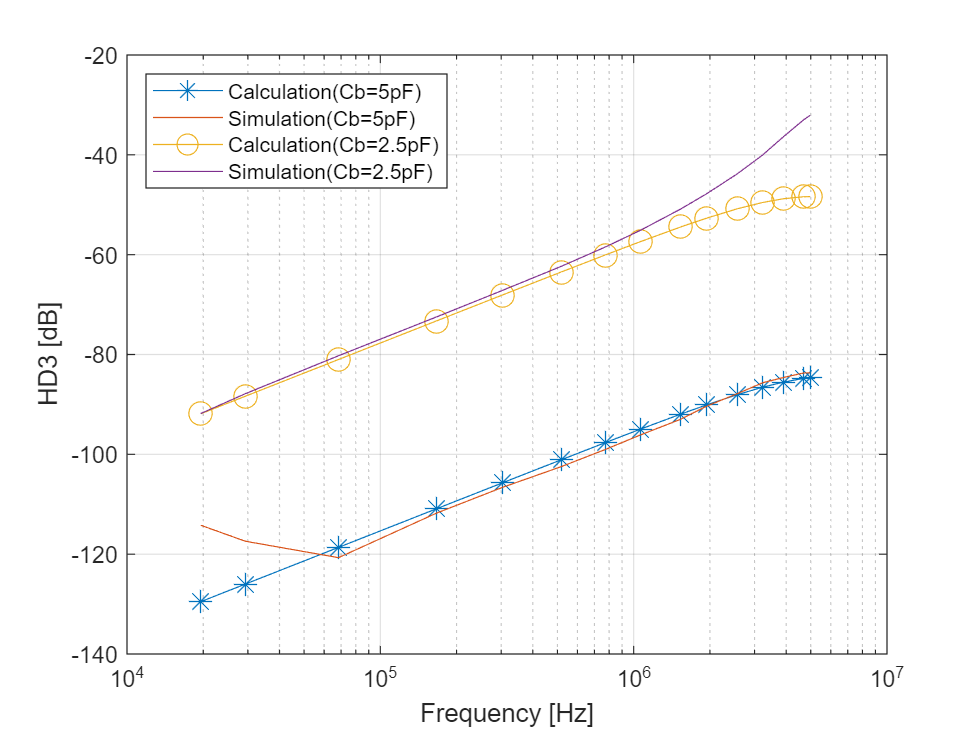

HD3_simulation_Cb1 = zeros(1, NUM_FRE);
HD3_simulation_Cb2 = zeros(1, NUM_FRE);
HD3_calculation_Cb1 = zeros(1, NUM_FRE);
HD3_calculation_Cb2 = zeros(1, NUM_FRE);

for i = 1:NUM_FRE
    [~, harmpow, ~] = thd(repmat(MCb1(:,i), 4, 1), Fs, 5, 'aliased');
    HD3_simulation_Cb1(i) = harmpow(3) - harmpow(1);
    [~, harmpow, ~] = thd(repmat(MCb2(:,i), 4, 1), Fs, 5, 'aliased');
    HD3_simulation_Cb2(i) = harmpow(3) - harmpow(1);
    HD3_calculation_Cb1(i) = getHD_Cap_Switch(V0, C1, Fin0(i), Fs, [5, 0, 1, 0]);
    HD3_calculation_Cb2(i) = getHD_Cap_Switch(V0, C1, Fin0(i), Fs, [2.5, 0, 1, 0]);
end
figure
semilogx(Fin0(index), HD3_calculation_Cb1(index), '-*', 'MarkerSize', 10)
hold on ;
semilogx(Fin0(index), HD3_simulation_Cb1(index))

semilogx(Fin0(index), HD3_calculation_Cb2(index), '-o', 'MarkerSize', 10)
semilogx(Fin0(index), HD3_simulation_Cb2(index))
grid on;
box on;
ylim([-140 -20])
xlabel("Frequency [Hz]");
ylabel("HD3 [dB]");
legend({'Calculation(Cb=5pF)', 'Simulation(Cb=5pF)', ...
    'Calculation(Cb=2.5pF)', 'Simulation(Cb=2.5pF)'}, "Location", "northwest")


getHD_Cap_Switch(V0, C1, Fin0(20), Fs, [5, 0, 1, 0])

ans = -98.5814

getHD_Cap_Switch(V0, C1, Fin0(20), Fs, [2.5, 0, 1, 0])

ans = -60.9752

for i = 1:NUM_FRE
%     [~, harmpow, ~] = thd(repmat(MCb1(:,i), 4, 1), Fs, 5, 'aliased');
%     HD3_simulation_Cb1(i) = harmpow(3) - harmpow(1);
%     [~, harmpow, ~] = thd(repmat(MCb2(:,i), 4, 1), Fs, 5, 'aliased');
%     HD3_simulation_Cb2(i) = harmpow(3) - harmpow(1);
    getHD_Cap_Switch(V0, C1, Fin0(i), Fs, [5, 0, 1, 0]);
%     HD3_calculation_Cb2(i) = getHD_Cap_Switch(V0, C1, Fin0(i), Fs, [2.5, 0, 1, 0]);
end

Csum = 1.5576

Csum = 1.5576

Csum = 1.5576

Csum = 1.5575

Csum = 1.5575

Csum = 1.5574

Csum = 1.5573

Csum = 1.5572

Csum = 1.5570

Csum = 1.5567

Csum = 1.5566

Csum = 1.5561

Csum = 1.5558

Csum = 1.5556

Csum = 1.5552

Csum = 1.5546

Csum = 1.5539

Csum = 1.5536

Csum = 1.5528

Csum = 1.5522

Csum = 1.5519

Csum = 1.5509

Csum = 1.5502

Csum = 1.5491

Csum = 1.5475

Csum = 1.5467

Csum = 1.5462

Csum = 1.5453

Csum = 1.5449

Csum = 1.5439

Csum = 1.5403

Csum = 1.5393

Csum = 1.5375

Csum = 1.5370

Csum = 1.5339

Csum = 1.5333

Csum = 1.5313

Csum = 1.5293

Csum = 1.5279

Csum = 1.5258

Csum = 1.5236

Csum = 1.5228

Csum = 1.5189

Csum = 1.5181

Csum = 1.5165

Csum = 1.5157

Csum = 1.5106

Csum = 1.5052

Csum = 1.5034

Csum = 1.5024

Csum = 1.5005

Csum = 1.4976

Csum = 1.4966

Csum = 1.4916

Csum = 1.4885

Csum = 1.4854

Csum = 1.4821

Csum = 1.4811

Csum = 1.4778

Csum = 1.4755

Csum = 1.4744

Csum = 1.4686

Csum = 1.4603

Csum = 1.4579

Csum = 1.4567

Csum = 1.4542

Csum = 1.4453

Csum = 1.4414

Csum = 1.4349

Csum = 1.4335

Csum = 1.4308

Csum = 1.4267

Csum = 1.4212

Csum = 1.4170

Csum = 1.4128

Csum = 1.4099

Csum = 1.4056

Csum = 1.3998

Csum = 1.3969

Csum = 1.3909

Csum = 1.3834

Csum = 1.3819

Csum = 1.3742

Csum = 1.3727

Csum = 1.3680

Csum = 1.3649

Csum = 1.3602

Csum = 1.3538

Csum = 1.3506

Csum = 1.3490

Csum = 1.3458

Csum = 1.3361

Csum = 1.3295

Csum = 1.3263

Csum = 1.3197

Csum = 1.3163

Csum = 1.3113

function HD3 = getHD_Cap_Switch(V0, C1, Fin, Fs, Carray)
% Carray = [Cb, Cp1, Cp2, Cp3]
% ~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~
% Parameter Settings
    VDD = 1.8;
    VTH = 0.457;
    mun = 280E-6;
    mWL = 32*12/0.2;
    KC = 0.82;
    Cp1 = 0;
    Cp2 = 0.34;
    Cp3 = 0.34;
    Ck1 = Carray(2)+Cp1 + Carray(3) + KC*Cp2;
    Ck2 = Carray(4) +KC*Cp3;
    Ctot = sum(Carray) + sum([Cp1, Cp2, Cp3]);
% ~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~
% calculate Vgs
    Vgs0 = (Carray(1)*1.8 - (Ck1 + Ck2)*0.9) / Ctot;
    phi = 2*pi*Fin*(1/(2*Fs));
    KFcos = cos(phi) ;
    KFsin = sin(phi) ;
    Csum = sqrt((Ck1^2+Ck2^2 + 2*Ck1*Ck2*cos(pi*Fin/Fs)));
    Vgs1 =  Csum / Ctot * V0 ;
%     Vgs0 - VTH
    KV = Vgs1 / (Vgs0 - VTH);

    Ron = 1/((Vgs0-VTH)*(mun * mWL));
    R2 = (KV^2 + KV^4) * Ron / 2;

% ~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~
% calculate results 
    HD3 = mag2db(R2*C1*Fin*pi);
end